# Main con switching potentials

Configuration space

clear; close all;
grid = Grid(100,11);

Obstacles and robot initial configuration

%Caso normale 5 ostacoli
grid.setGoal([8,10]);
grid.addObstacle(Obstacle(2,4,[1;0]));
grid.addObstacle(Obstacle(10,6,[-1;0]));
grid.addObstacle(Obstacle(2,10,[0.6;-0.25]));
grid.addObstacle(Obstacle(8,10,[-0.4;-0.5]));
grid.addObstacle(Obstacle(10,5,[-0.4;0.2]));

%Problema che sbatte con un raggio h (o di visione) troppo piccolo
% grid.setGoal([5,10]);
% grid.addObstacle(Obstacle(3,5,[1;0]));
% grid.addObstacle(Obstacle(10,6,[-1;0]));
% grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));

%Gli arriva dritto in faccia e deve ingrandire la circonferenza
% grid.addObstacle(Obstacle(5,5,[0;-0.7]));

%Non ci sbatte senza evitarlo
% grid.addObstacle(Obstacle(2,1,[1;0.3]));

%Ostacolo sbatte al muro
% grid.addObstacle(Obstacle(7,2,[0.5;0.8]));

% grid.addObstacle(Obstacle(2,2,[1;0.3]));
% grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));

n = length(grid.obstacles);
r = SwitchingRobot(0.15,0.3,grid,0.05);

Inizio simulazione

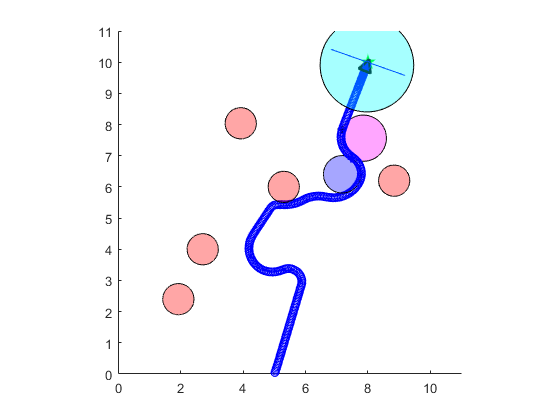

r.start();